# **River profile and catchment analysis**

In this script, you'll learn how to extract longitudinal river profiles and analyse them in terms of difference in bedrock erodbility and tectonics of southwestern Germany. Additionally, there will be analysis of knickpoints and how we can use them to extract tectonic information.

clc
clear 
close all
DEM = GRIDobj('../data/BW_DEM.tif'); % load DEM
DEM.Z(end,:)= 2000;                  % condition DEM that streams don't flow south
DEM.Z(DEM.Z == 0) = nan;   % during projection some of the DEM pixels were set to zero though they should be NaN.

Let's calculate the stream network. Use a minimum drainage area of 5 km² and carve the flow directions. 

FD  = FLOWobj(DEM,'preprocess','carve');
A  = flowacc(FD);
S = STREAMobj(FD,'minarea',10e6,'unit','map'); % delineate stream network

A common way of loooking at river networks is to investigate their longitudinal profiles. 

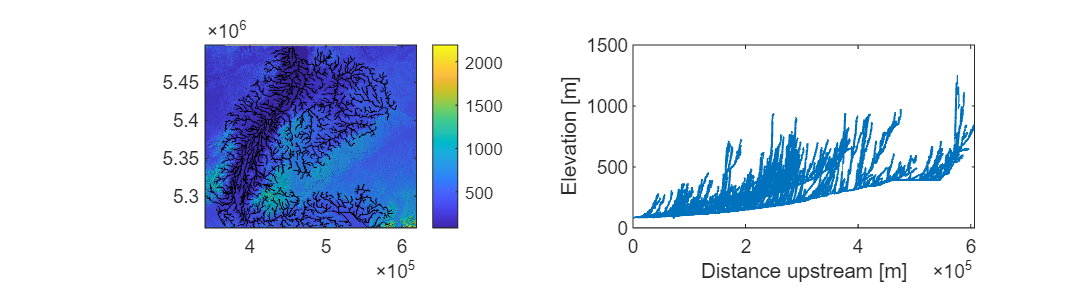

Smod = klargestconncomps(S);  % selects the longest connected stream network in the study region

figure();
set(gcf,'Units','normalized','Position',[0 0 1 .5]); 
tiledlayout(1,2)
nexttile
imageschs(DEM);  % plot your DEM
hold on
plot(Smod,'k-')  % plot the stream nework on top of the DEM as black lines -> 'k-'

nexttile
plotdz(Smod,DEM)  % use the plotdz function to plot the river profile

Wow, that's a lot of lines at once! Zoom into the river profiles a bit. What do you notice?

The profiles are pretty wiggly due to DEM errors! This means we should smooth our river profile elevations. Smoothing is an art in itself, and TT provides several ways of doing this. If you're computer is a bit slower use 'smooth', otherwise try using 'crs' (took 89 seconds on my fast laptop) and comment the other line out. CRS (constrained regularized smoothing) makes sure no negative stream gradients occur and calculates a smooth splin through the noisy DEM elevation values.

K = 17

K = 17

% Z = smooth(Smod,DEM,'K',K);
Z = crs(Smod,DEM,'K',K, 'mingradient',0 , 'tau', 0.25, 'split',false);

Elapsed time is 88.379003 seconds.


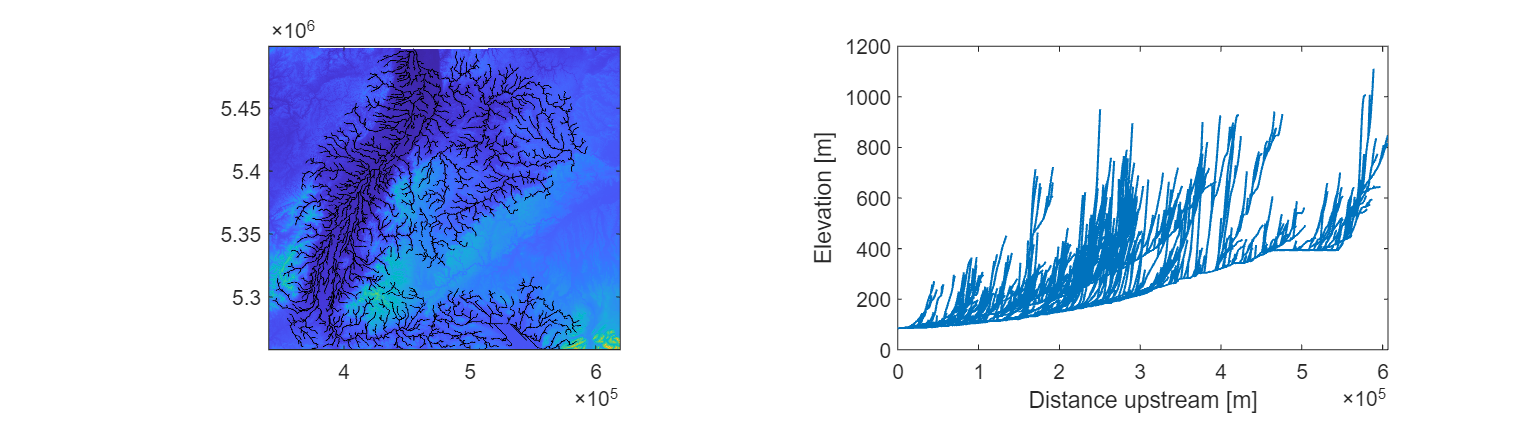

figure();
set(gcf,'Units','normalized','Position',[0 0 1 .5]); 
tiledlayout(1,2)
nexttile
imagesc(DEM);    % plot DEM
hold on
plot(Smod,'k-')    % plot stream on top of DEM

nexttile
plotdz(Smod,Z);    % plot elevation profile of stream

You might notice that there are still some spots, where the river channels flow uphill. This of course makes no sense. There are several ways of treating this. The best way of smoothing river profiles is smoothing called crs (constrained regularized smoothing), which is the most sophistacted (but also slowest) smoothing function for TT.

The smaller the drainage area of a river, the steeper its channel. This relationship is often referred to as Flint's law:


$$S=k_s *A^{-\Theta }$$


where channel slope S scales with drainage area, to the power of the so-called concavity. $k_s$ is the river steepness normalized for the downstream increase in drainage area. To compare the river steepness $k_s$ between streams, we need to hold the concavity constant. Luckily for us, concavity usually doesn't change so much on our planet, and is commonly around 0.45 to 0.5. Using the same concavity between streams is called a reference concavity and the channel steepness with a reference concavity is the normalized channel steepness $k_{\textrm{sn}}$. 

theta_ref = 0.45;

### River steepness Ksn

Remember that the river steepness is used a lot because it tells us about tectonic uplift (U) and bedrock erodibility (+climate) (K).

$k_{\textrm{sn}} ={\left(\frac{U}{K}\right)}^{\frac{1}{n}}$  can also be written with erosion rate E:  $k_{\textrm{sn}} ={\left(\frac{E}{K}\right)}^{\frac{1}{n}}$

n - is an empirical parameter often assumed to be = 1, and therefore can for our purposes be neglected.

Calculate $k_{\textrm{sn}}$ with the reference concavity and the smooth parameter from before. Before the $k_{\textrm{sn}}$ commaned we should still smooth the stream elevations. Earlier, we only smoothed elevations for the Rhine river basin, not the entire DEM.

Z = smooth(S,DEM,'K',10);
Z = quantcarve(S,Z,0.25, 'split', false);
Ksn = loessksn(S,Z,A,'mn',theta_ref,'parallel',false);   

Just as a side note. TT now also comprises the function 'loessksn' that uses a locally weighted scatterplot smoothing to calculate ksn. If you're like me and don't exactly now that a LOESS regresison is, you can watch this nice [explanation video](https://www.youtube.com/watch?v=Vf7oJ6z2LCc).

Now, let's make a nice Ksn map. Plot the DEM using a black and white gradient and plot ksn on top.

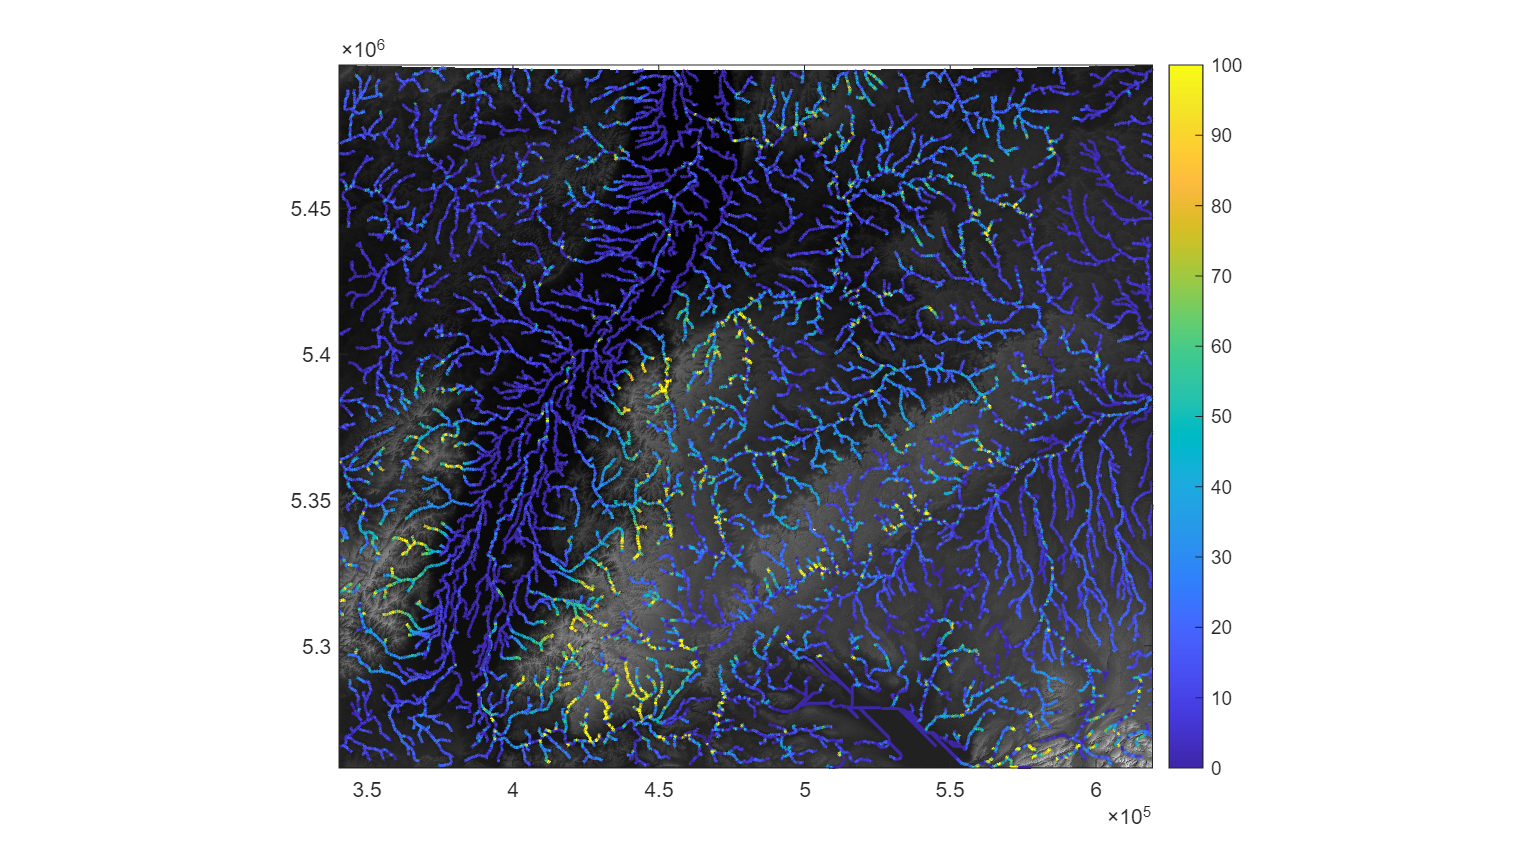

cm = gray(255);
h = figure();
set(h,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,[],'colormap',cm,'colorbar',false)
hold on
plotc(S,Ksn)
colorbar
caxis([0,100])

Under uniform climatic, lithologic conditions, tectonic conditions through time all rivers should evolve to the same Ksn. Therefore, variations, in Ksn are used to infer variations in erodibility and uplift rate in space and time. 

### Interpreting Ksn patterns

We have now computed the river steepness. Maps of river steepness are typically used to infer patterns of bedrock erodbility, tectonics, and climate. But how to do this? 

Climate influence is often the hardest to show and requires substantial rainfall gradients. Since, rainfall is relatively uniform in this area (and because we only have limited time in this course), we'll focus on the more obvious tectonics and bedrock geology.

Try to interpret the Ksn map in terms of spatial patterns in tectonics and geology and discuss with your peers.

## The effect of bedrock geology on topography

We've seen that bedrock geology seems to have quite a strong control on topography in the region, as exemplified by all the cuesta's formed due to the hard rocks. Let's see if we can quantify this influence.

GEO = GRIDobj('../data/Geo_BW.tif');
GEO = resample(GEO,DEM,'nearest');

% group lithologies
ids = cell(6,1);                                % empty lithology ID matrix
ids{1} = 1;                                  % unconsolidated sediments
ids{2} = [7,8,9,10,11,12,13];                % Magmatic, Metamorphic
ids{3} = 2;                                  % siliciclastic sediments
ids{4} = 4;                                  % mixed sediments
ids{5} = 5;                                  % carbonates
ids{6} = [6 14 15 16];                       % Other: evaporites, water, ice and no data
geo_names = {'unconsolidated  sediment','basement', 'siliciclastic  sediment', 'mixed  sediment', 'carbonates','other'};

simpleGEO = GEO;
for i =1:length(ids)
    simpleGEO.Z(ismember(GEO.Z, ids{i})) = i;
end

Let's visually check the geologic map

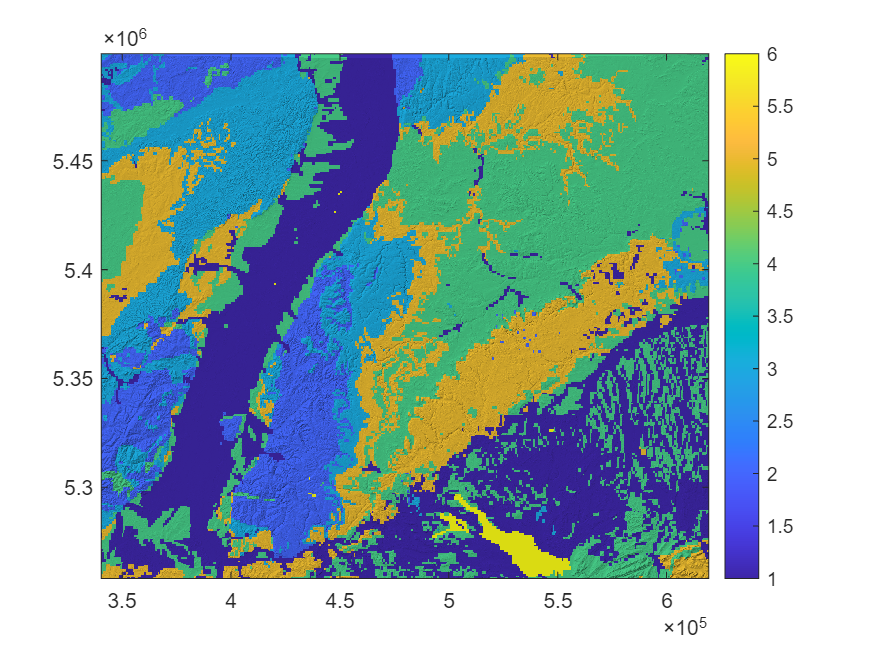

figure()
imageschs(DEM,simpleGEO)
colorbar

### Steepness per lithology

Let's calculate the slope in degrees and comare it amongst different geologic units. 

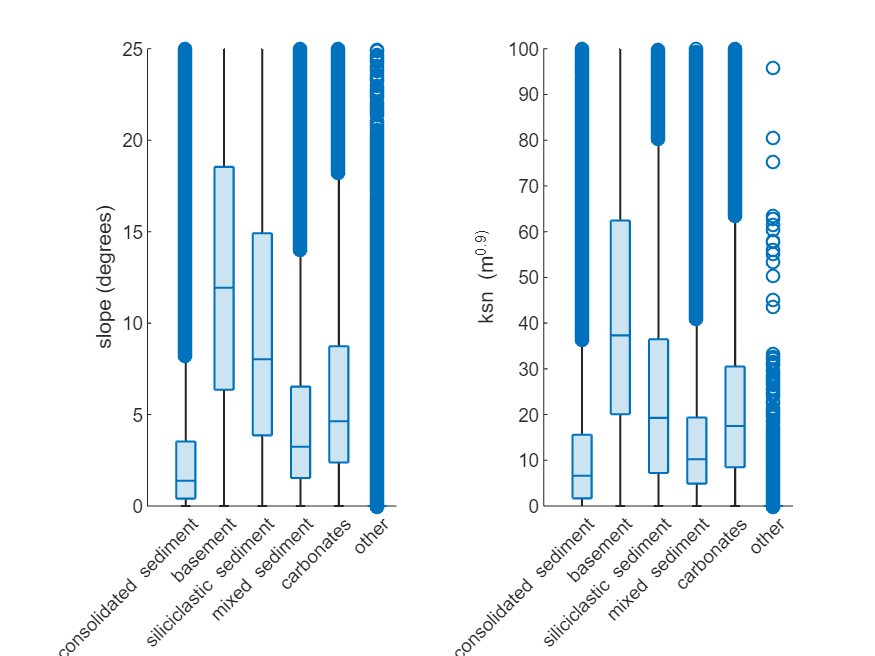

slope = gradient8(DEM,'degree');
geo_streams = getnal(S,simpleGEO);

figure()
tiledlayout(1,2)
nexttile
boxchart(simpleGEO.Z(:),slope.Z(:))
xticks(1:6)
xticklabels(geo_names)
ylabel('slope (degrees)')
ylim([0 25])

nexttile
boxchart(geo_streams,Ksn)
xticks(1:6)
xticklabels(geo_names)
ylabel('ksn (m^0.9)')
ylim([0 100])

The relative differences for Ksn and slope between lithologies look similar. This is not always true, otherwise geomorphologists would always just use the easier and faster to calculate slope values for interpretation. Can you guess under which circumstances slope is less useful and why river steepness became the standard steepness metric of topography?

- Slopes typically reach a threshold value above which landsliding occurs. However, rivers can continue to steepen ever under very high tectonic uplift or hard bedrock conditions.

- the siliciclastic sediments (mostly sandstones) form relatively steep slopes but comparatively less steep rivers. Likely the sandstones are hard to erdode by hillslope erosion processes, but are weaker in terms of river erosion processes.

## Erosion rate map

Using our observations of differential steepness of rock types, we can make a VERY ROUGH estimate of erosion rates distributions. All we need for this is our channel steepness $k_{\textrm{sn}}$ and the some independent erosion data. Fom cosmogenic nuclides we know that the crystalline basement rock in the Black Forst erode at approximately 50 mm/ka (Morel et al. 2003, [link](https://doi.org/10.1046/j.1365-3121.2003.00519.x)). If we assume that the tectonic uplift rate within the area is more or less equal, we can can calculate relative erodbilities fr the rock units from the differences in $k_{\textrm{sn}}$ and scale them with our known erosion rate for crystalline bedrock units. These erodbilities can then be used with our $k_{\textrm{sn}}$ map to estimate erosion rate. 

Why? Look back at the equation for $k_{\textrm{sn}} ={\left(\frac{E}{K}\right)}^{\frac{1}{n}}$

We can rearrange this to $E=K*k_{\textrm{sn}} \;\;,\textrm{assuming}\;n=1$

Assumption of uniform tectonics: We've already established that tectonic uplift likely varies regionally, but it is difficult to constrain variations in erodbility and tectonics at the same time. So, let's leave tectonics out for now and focus on getting a rough spatial estimate for natural erosion rates.

Strategy:

- Calculate median $k_{\textrm{sn}}$ per lithologic unit

- Divide erosin rate by median $k_{\textrm{sn}}$ for all units to get an erodbiity estimate!

- Make an erodibility map from the geologic map

- Make a $k_{\textrm{sn}}$ map from your stream $k_{\textrm{sn}}$ values, by projecting values from streams onto the hillslopes

- Multiply erodbility and $k_{\textrm{sn}}$ map to get erosion: $E=K*k_{\textrm{sn}}$

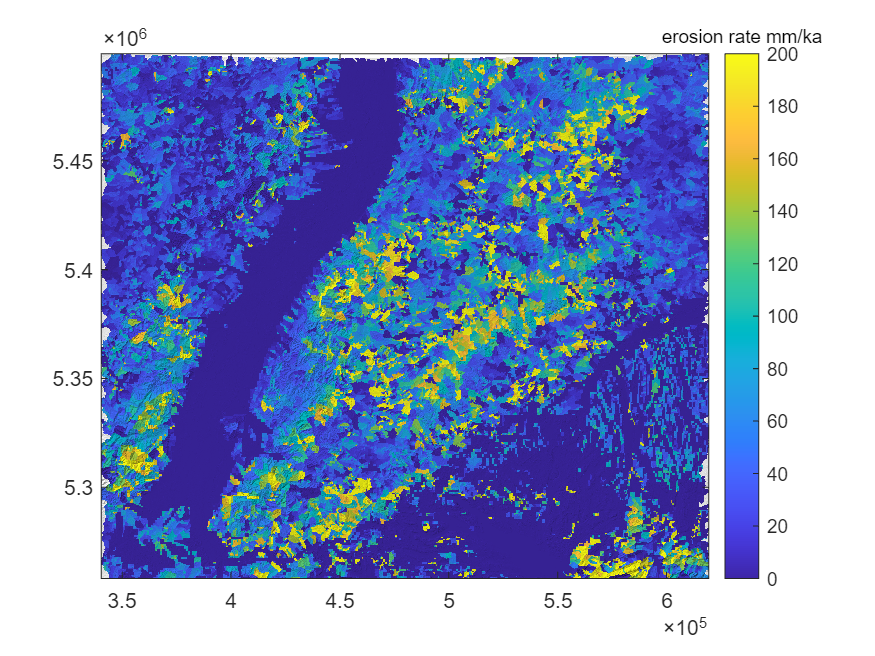

erosion_rate = 50; % mm/ka

% median Ksn per rock unit
medians_per_geo = nan(numel(ids),1);
for i = 1:numel(ids)
    medians_per_geo(i) = median(Ksn(geo_streams == i), 'omitnan');
end
Ke = erosion_rate ./ medians_per_geo;  % erodbilities

Ke(1) = 0;  % set unconsolidated sediment to zero
Ke(6) = 0;  % set ice, water, etc to zero

Ke_map = simpleGEO;  % copy geologic map for new erodibility map
for i =1:numel(Ke)   % loop over rock units
    Ke_map.Z(simpleGEO.Z == i) = Ke(i);  % set erodbility for every rock unit
end

Ksn_map = mapfromnal(FD,S,Ksn);   % project Ksn fro streams onto neighboring hillslopes

erosion_map = Ke_map * Ksn_map;   % calculate erosion rate, leaving out ^n, because n assumed to be 1

% plot erosion rate map
figure()
imageschs(DEM,erosion_map, 'clim',[0 200], 'colorbarlabel','erosion rate mm/ka')

Interpret this map. The map assumes that erosion on the hillslopes is as fast as the river erodes—that's why we could use $k_{\textrm{sn}}$, a common assumption that is probably OK. It also assumes that uplift is more or less constant. We know that this is wrong to a certain degree. In which areas are we likely underestimating and overestimating erosion?

The Black Forest is probably uplifting faster than most other areas, which could lead to underestimated rates of erosion in that area. 

### Rhine vs Danube

Let's check if the two major river systems have different erosion rates and are therefore likely to undergo drainage reorganization.

Use 'drainagebasins' to calculate a map of drainage basins. I've already selected the correct indices from the DB map for you. If you wanted to select them yourself you can plot DB with 'imagesc' and use the 'data tip' tool in the Matlab figure window figure out which basin has which index.

DB = drainagebasins(FD);

Rhine_idx = 1;
Danube_idx = 368;

avg_erosion_Rhine  = median(erosion_map.Z(DB.Z == Rhine_idx))

avg_erosion_Rhine = single
33.2904

avg_erosion_Danube = median(erosion_map.Z(DB.Z == Danube_idx))

avg_erosion_Danube = single
11.1418

## OPTIONAL BUT FUN PART: River profiles and time!

Geomorphologists often study river profiles—the elevation profile of a river along its course. While Ksn is mostly used to assess spatial variations in K and U, a river profile is especially suited to investigate temporal changes in U (and K if you include climate), and how the landscape evolves over time. 

Use the interactive mode of the 'modify' function to pick a drainage basin you want to investigate. Click on the outlet of the drainage basin and click a button. It will be automatically saved as variable, ready for you to plot.

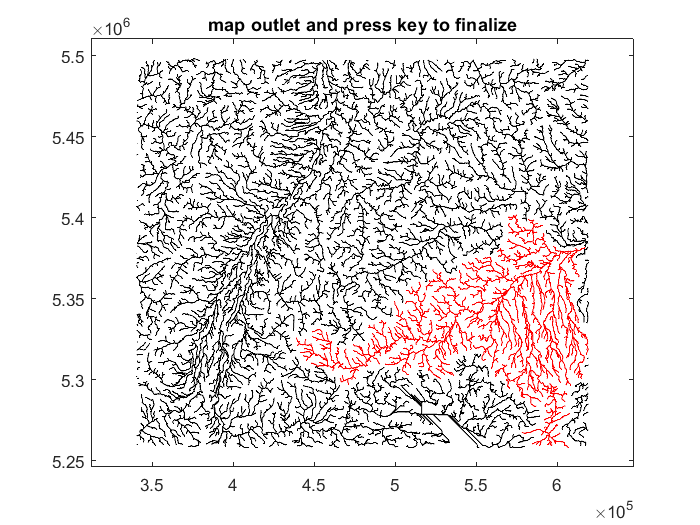

S_selected = modify(S,'interactive', 'outletselect');

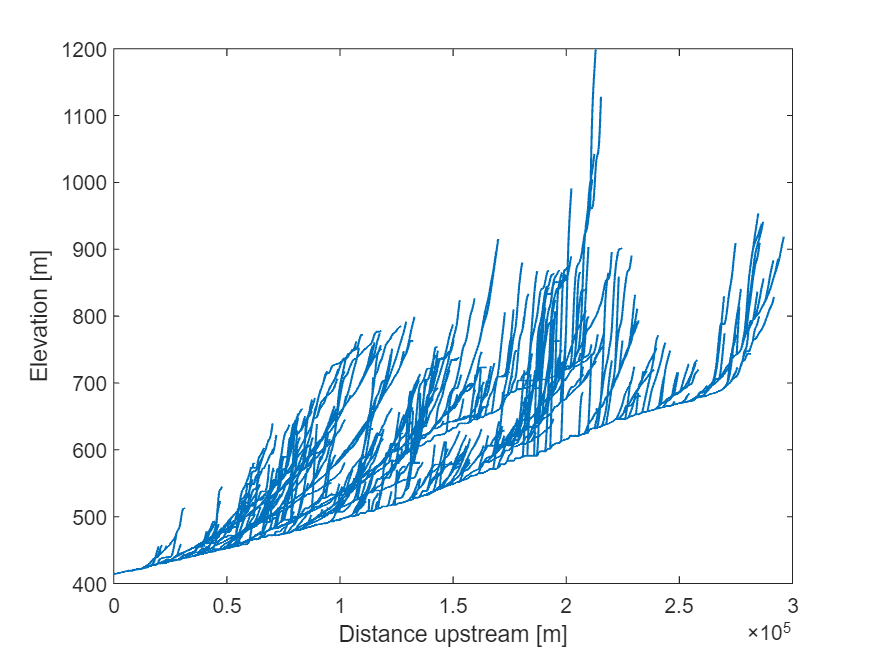

figure()
Z = smooth(S_selected,DEM,'K',20);
plotdz(S_selected,Z);

There are many options to selected streams (see help for modify function—interactive). You can select the stream channel head. Or all streams within an area.  Check the help in the 'modify' function.

You're now seing the normal elevayion vs distance profile of a stream. As we've discussed streams are usually concave because of the non-linear downstream increase in discharge/drainage area. If you see convex segments in your profile, something is happening related to tectonics or bedrock in either time or space.

Play around with this tool and look at several river profiles. Use the different modes of the interactive selection in modify. Get familiar with the function and the way river profiles look like in the area.

### Chi

There's a different way of plotting the elevation profile, and that is by plotting chi instead of distance on the x-axis. The equation is


$$\chi =\int_{\mathrm{x0}}^x {\left(\frac{A_0 }{A}\right)}^{\frac{m}{n}} \mathrm{dx}\;\ldotp \;$$


A0 is a reference drianage area that is just introduced to keep the units in meters. A0 is typically set to 1 m². x0 is the location of base level.

Think about the equation a bit. What is chi exactly calculating in your own words? 

There's an integration that moves upstream and you add the reciprocal of the drainage area and acounts for the stream concavity (m/n ratio). Therefore, chi is like a upstream distance that accounts for the increase in drainage area. A perfectly concave stream elevation profile turns into a straight line in a chi-plot.

Moreover, all tributaries collapse onto a line. Tributaries are steeper than the trunk in the normal river profile, because they have less drainage area and therefore higher slope. Chi accounts for these differences in drainage area. Thus, interpreting a chi-plot is usually much more informative than looking at the "normal" longitudinal river profile to identify changes in the river steeness Ksn.

Elevation versus distance (normal longitudinal river profile) of a trunk stream and tributaries in West Virginia, US. And a Chi-profile from the same stream network, showing how transforming the x-coordinate from distance to chi account for differences in drainage area and collapses all rivers onto the same line = same Ksn (from Perron and Royden 2013). 

Let's look at an example stream I selected.

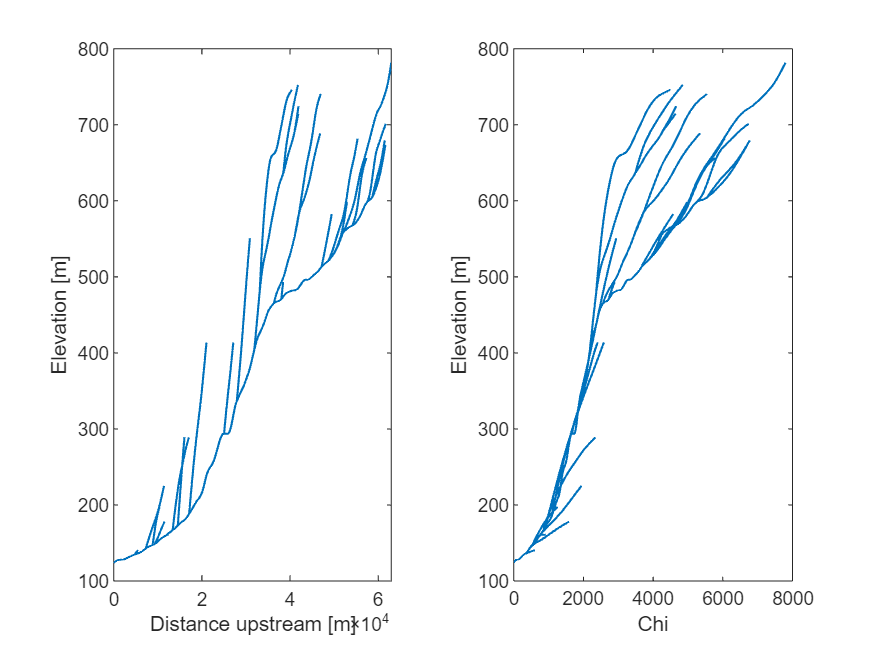

IX_stream      = 3123549;    % linear index into DEM of stream outlet to look at
example_stream = modify(S,'upstreamto',IX_stream);

figure()
tiledlayout(1,2)

% plot elevation profile
nexttile
Z = smooth(example_stream,DEM,'K',20);
Z = quantcarve(example_stream,Z,0.25, 'split', false);
plotdz(example_stream,Z);hold on


% plot chi profile
nexttile
chi_stream = chitransform(example_stream,A,"mn",theta_ref);
plotdz(example_stream,Z,'distance',chi_stream);
xlabel('Chi')

As you see the chi-plot is more linear than the elevation profile. This is because steady-state river segments become straight, because chi accounts for the downstream increase in discharge/drainage area. The slope of the line in the chi-plot is equal to Ksn! So, you can directly interpret the stream steepness from these plots.

The lowest 3 tributaries were steeper than the elevation profile of the trunk stream, but are the same steepness in the chi-profile. Why?

As I said, chi accounts for the increase in discharge. The tribuatores have a higher slope but their channel steepness normalized for the amount of discharge is the same. In steady-state reaches, all tributaries and the trunk stream collapse onto a line! **Therefore, we can immedeatly use chi-plot to assess steady-state stream profiles.**

The upstream segment of this river network has a lower slope (Ksn) than the downstream portion. If you check the geologic map, you'll see that the whole stream flows through basement rocks. Therefore, there is likely no significant change in erodibility. The part of the stream we plotted also does not cross any major faults. 

Since, we've checked for spatial varitions in U and K, this change in river slope is likely a temporal signal of a transient stream profile, potentially related to an increase in slip rate (and therefore uplift rate) of the graben bounding faults at the outlet of the stream. The point where the main stream changes its slope is called a knickpoint.

If U and K are assumed to be constant in space (and n=1), then $k_{\textrm{sn}}$ should be proportional to U (remember $k_{\textrm{sn}} ={\left(\frac{U}{K}\right)}^{\frac{1}{n}}$ with n=1 --> $k_{\textrm{sn}} =\frac{U}{K}$--> $k_{\textrm{sn}}$ ~ U).

Therefore, we can calculate the $k_{\textrm{sn}}$ above and below the knickpoint and the change in $k_{\textrm{sn}}$ should be proportional to the change in tectonic uplift. 

kp_chi = 2700;

above_kp = chi_stream > kp_chi;
below_kp = chi_stream < kp_chi;

Ksn_stream = loessksn(example_stream,Z,A,'mn',theta_ref, 'parallel', false);

Ksn_above_kp = median(Ksn_stream(above_kp))

Ksn_above_kp = 34.0309

Ksn_below_kp = median(Ksn_stream(below_kp))

Ksn_below_kp = 57.1131

Ksn_below_kp/Ksn_above_kp

ans = 1.6783

Ksn below the knickpoint is about 70% higher than above, which corresponds to an 70% increase in uplift, and therefore fault slip rate. If we'd assume an erodibility for the granite (which is not easy to quantify), then we could even calculate WHEN fault slip doubled.

Now, at this point I'd like you to sit back and think about what we've achieved here. We've used simple elevation data and (i) identified an active fault that poses a significant earthquake hazard, (ii) figured out that fault slip probably changed through time, and (iii) estimated by how much fault slip increased. This is vital information for seismic hazard assessment! Paleoseismologist spend lots of money on digging trenches, dating, and interpreting fault deposits to answer such questions, and we did it with our laptop spending 0 €.

You can also map knickpoints automatically in TopoToolbox. There's a tool called 'knickpoitfinder' that works moderately well at identifying knickpoints. You can test it! Though it will take a while to run.

25-Sep-2025 14:11:35 -- Starting
25-Sep-2025 14:11:55 -- Iteration: 1, 1 knickpoints, max dz: 236.974
25-Sep-2025 14:12:11 -- Iteration: 2, 5 knickpoints, max dz: 159.9136
25-Sep-2025 14:12:28 -- Iteration: 3, 7 knickpoints, max dz: 159.1012
25-Sep-2025 14:12:48 -- Iteration: 4, 9 knickpoints, max dz: 140.1603
25-Sep-2025 14:13:10 -- Iteration: 5, 11 knickpoints, max dz: 131.7502
25-Sep-2025 14:13:27 -- Iteration: 6, 13 knickpoints, max dz: 123.9063
25-Sep-2025 14:13:43 -- Iteration: 7, 16 knickpoints, max dz: 107.8359
25-Sep-2025 14:14:03 -- Iteration: 8, 18 knickpoints, max dz: 104.0604
25-Sep-2025 14:14:20 -- Iteration: 9, 21 knickpoints, max dz: 98.9265
25-Sep-2025 14:14:37 -- Iteration: 10, 23 knickpoints, max dz: 97.9201
25-Sep-2025 14:14:55 -- Iteration: 11, 25 knickpoints, max dz: 95.7837
25-Sep-2025 14:15:12 -- Iteration: 12, 27 knickpoints, max dz: 93.086
25-Sep-2025 14:15:30 -- Iteration: 13, 29 knickpoints, max dz: 93.0107
25-Sep-2025 14:15:48 -- Iteration: 14, 31 knickpoin

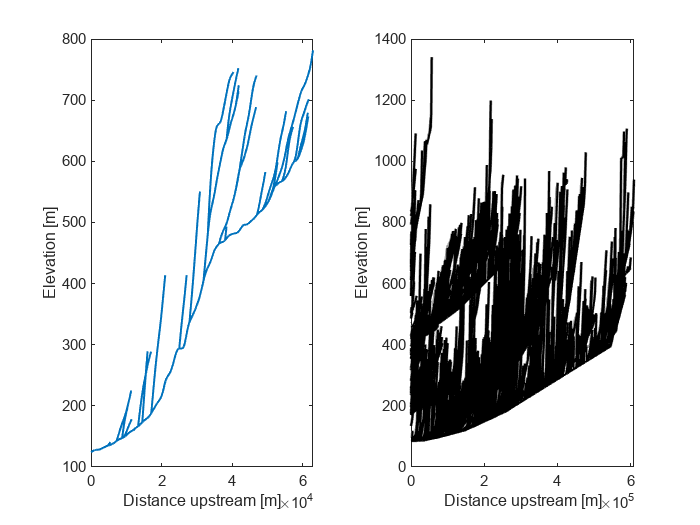

Z = smooth(S,DEM,'K',10);
Z = quantcarve(S,Z,0.25,'split', false);

figure()
[zk,kp] = knickpointfinder(S,Z,'split',false,'plot',true,'tol',50);  % the tolerance value is the difference between the modelled and observed stream network

% if the difference between model network and real network is larger than
% the tolerance value, the function maps a knickpoint. The function is
% pretty slow. You might need to take a brake. The smaller the tol value,
% the more knickpoints you'll find, and the longer the function will run.


Time to introduce a new object in TT—PPS point patterns on stream network. Often we work with points along stream networks, like the gauging stations in excercise 4, or here knickpoints. PPS is a convenient way of storing points and the associated stream network together with some nice plotting options. Check out the commands below.

P = PPS(S,'pp',kp.IXgrid,'z',Z);   % make PSS with current STREAMobj and knickpoints

figure()
tiledlayout(1,3)
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
nexttile
imageschs(DEM,[])
hold on
plot(P)
title('streams map view with kp')
nexttile
plotdz(P)
title('long. stream profile with kp')
nexttile
plotdz(P,'distance',chitransform(S,A),'SizeData',kp.dz)
title('chi profile with kp')